# Producing the Chloroplast Carbon Metabolism Model directly in the COBRA toolbox

changeCobraSolver('ibm_cplex');

Gurobi installed at this location? 
Licence file current? 
Version identifier: 12.10.0.0 | 2019-11-26 | 843d4de2ae
CPXPARAM_Output_WriteLevel                       3
CPXPARAM_Output_CloneLog                         -1
Found incumbent of value 0.000000 after 0.00 sec. (0.00 ticks)

Root node processing (before b&c):
  Real time             =    0.00 sec. (0.00 ticks)
Parallel b&c, 8 threads:
  Real time             =    0.00 sec. (0.00 ticks)
  Sync time (average)   =    0.00 sec.
  Wait time (average)   =    0.00 sec.
                          ------------
Total (root+branch&cut) =    0.00 sec. (0.00 ticks)
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

   --------------------------------------------------------
   pdco.m                 

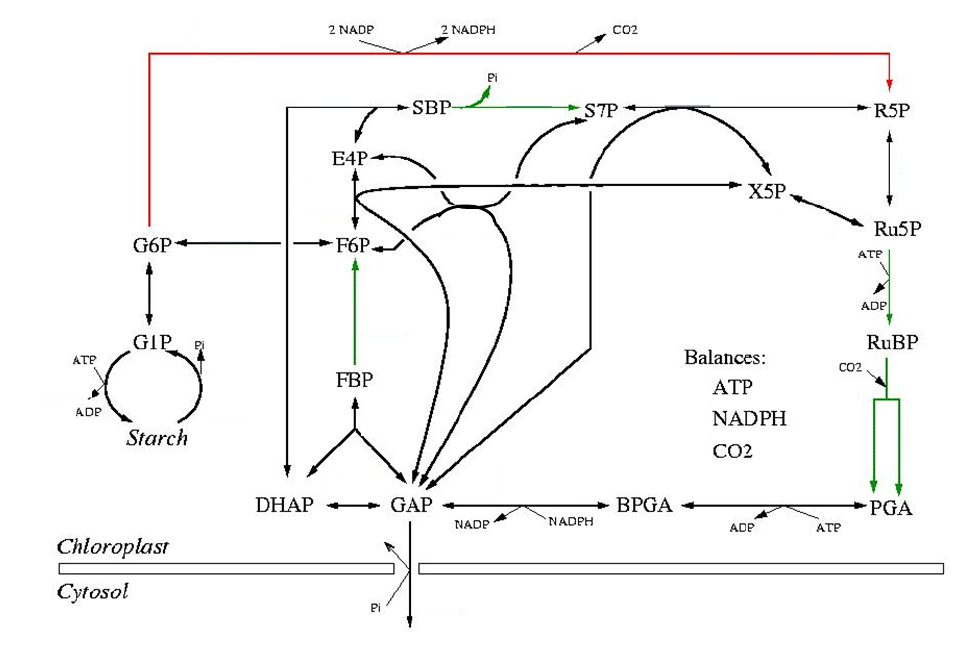

## a) Create a constraint-based model of a simple biochemical system directly in COBRA using the createModel command.

Creat a new COBRA model with the following reactions

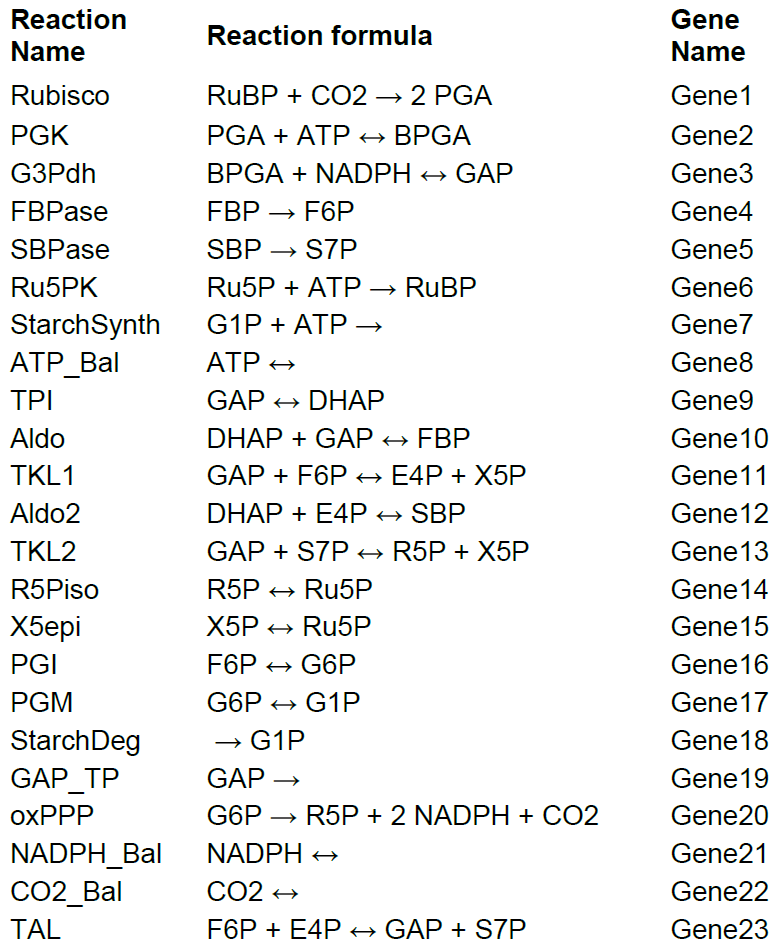

ReactionFormulas = {'RuBP + CO2 -> 2 PGA','PGA + ATP <=> BPGA',...
    'BPGA + NADPH <=> GAP','FBP -> F6P','SBP -> S7P',...
    'Ru5P + ATP -> RuBP','G1P + ATP ->',...
    'ATP <=>','GAP <=> DHAP','DHAP + GAP <=> FBP','GAP + F6P <=> E4P + X5P',...
    'DHAP + E4P <=> SBP','GAP + S7P <=> R5P + X5P','R5P <=> Ru5P',...
    'X5P <=> Ru5P','F6P <=> G6P','G6P <=> G1P','-> G1P','GAP ->',...
    'G6P -> R5P + 2 NADPH + CO2','NADPH <=>','CO2 <=>',...
    'F6P + E4P <=> GAP + S7P'};

ReactionNames = {'v1','v2','v3','v4','v5','v6','v7','v8','v9','v10',...
    'v11','v12','v13','v14','v15','v16','v17','v18','v19','v20','v21','v22','v23'};

GeneNames={'Gene1','Gene2','Gene3','Gene4','Gene5','Gene6','Gene7','Gene8','Gene9','Gene10',...
    'Gene11','Gene12','Gene13','Gene14','Gene15','Gene16','Gene17','Gene18','Gene19','Gene20','Gene21','Gene22','Gene23'};

orig_model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

Adding the following Metabolites to the model:
ATP[c]
BPGA[c]
CO2[c]
DHAP[c]
E4P[c]
F6P[c]
FBP[c]
G1P[c]
G6P[c]
GAP[c]
NADPH[c]
PGA[c]
R5P[c]
Ru5P[c]
RuBP[c]
S7P[c]
SBP[c]
X5P[c]
addMultipleReactions: Adding the following reactions to the model:
v1	CO2[c] + RuBP[c] 	->	2 PGA[c] 
v2	ATP[c] + PGA[c] 	<=>	BPGA[c] 
v3	BPGA[c] + NADPH[c] 	<=>	GAP[c] 
v4	FBP[c] 	->	F6P[c] 
v5	SBP[c] 	->	S7P[c] 
v6	ATP[c] + Ru5P[c] 	->	RuBP[c] 
v7	ATP[c] + G1P[c] 	->	
v8	ATP[c] 	<=>	
v9	GAP[c] 	<=>	DHAP[c] 
v10	DHAP[c] + GAP[c] 	<=>	FBP[c] 
v11	F6P[c] + GAP[c] 	<=>	E4P[c] + X5P[c] 
v12	DHAP[c] + E4P[c] 	<=>	SBP[c] 
v13	GAP[c] + S7P[c] 	<=>	R5P[c] + X5P[c] 
v14	R5P[c] 	<=>	Ru5P[c] 
v15	X5P[c] 	<=>	Ru5P[c] 
v16	F6P[c] 	<=>	G6P[c] 
v17	G6P[c] 	<=>	G1P[c] 
v18		->	G1P[c] 
v19	GAP[c] 	->	
v20	G6P[c] 	->	CO2[c] + 2 NADPH[c] + R5P[c] 
v21	NADPH[c] 	<=>	
v22	CO2[c] 	<=>	
v23	E4P[c] + F6P[c] 	<=>	GAP[c] + S7P[c] 


model=orig_model;
% finally print reactions in the model
printRxnFormula(model,model.rxns);

v1	CO2[c] + RuBP[c] 	->	2 PGA[c] 
v2	ATP[c] + PGA[c] 	<=>	BPGA[c] 
v3	BPGA[c] + NADPH[c] 	<=>	GAP[c] 
v4	FBP[c] 	->	F6P[c] 
v5	SBP[c] 	->	S7P[c] 
v6	ATP[c] + Ru5P[c] 	->	RuBP[c] 
v7	ATP[c] + G1P[c] 	->	
v8	ATP[c] 	<=>	
v9	GAP[c] 	<=>	DHAP[c] 
v10	DHAP[c] + GAP[c] 	<=>	FBP[c] 
v11	F6P[c] + GAP[c] 	<=>	E4P[c] + X5P[c] 
v12	DHAP[c] + E4P[c] 	<=>	SBP[c] 
v13	GAP[c] + S7P[c] 	<=>	R5P[c] + X5P[c] 
v14	R5P[c] 	<=>	Ru5P[c] 
v15	X5P[c] 	<=>	Ru5P[c] 
v16	F6P[c] 	<=>	G6P[c] 
v17	G6P[c] 	<=>	G1P[c] 
v18		->	G1P[c] 
v19	GAP[c] 	->	
v20	G6P[c] 	->	CO2[c] + 2 NADPH[c] + R5P[c] 
v21	NADPH[c] 	<=>	
v22	CO2[c] 	<=>	
v23	E4P[c] + F6P[c] 	<=>	GAP[c] + S7P[c] 


disp([model.rxns num2cell(model.lb) num2cell(model.ub)])

    'v1'     [    0]    [1000]
    'v2'     [-1000]    [1000]
    'v3'     [-1000]    [1000]
    'v4'     [    0]    [1000]
    'v5'     [    0]    [1000]
    'v6'     [    0]    [1000]
    'v7'     [    0]    [1000]
    'v8'     [-1000]    [1000]
    'v9'     [-1000]    [1000]
    'v10'    [-1000]    [1000]
    'v11'    [-1000]    [1000]
    'v12'    [-1000]    [1000]
    'v13'    [-1000]    [1000]
    'v14'    [-1000]    [1000]
    'v15'    [-1000]    [1000]
    'v16'    [-1000]    [1000]
    'v17'    [-1000]    [1000]
    'v18'    [    0]    [1000]
    'v19'    [    0]    [1000]
    'v20'    [    0]    [1000]
    'v21'    [-1000]    [1000]
    'v22'    [-1000]    [1000]
    'v23'    [-1000]    [1000]



## b) Investigate two different settings (day vs night) by setting the bounds for starch synthesis, starch degradation and RUBISCO appropriately and optimize for maximal GAP transport to the cytosol.

Day: RUBISCO=24, StarchSynth=2 and StarchDeg=0

Night: RUBISCO=0, StarchSynth=0 and StarchDeg=1

## Define system boundaries: night

% RUBISCO = 0
model = changeRxnBounds(model,{'v1'},[0],'b');
% starch synthesis = 0
model = changeRxnBounds(model,{'v7'},[0],'b');
% starch degradation = 1
model = changeRxnBounds(model,{'v18'},[1],'b');
disp([model.rxns num2cell(model.lb) num2cell(model.ub)]);

    'v1'     [    0]    [   0]
    'v2'     [-1000]    [1000]
    'v3'     [-1000]    [1000]
    'v4'     [    0]    [1000]
    'v5'     [    0]    [1000]
    'v6'     [    0]    [1000]
    'v7'     [    0]    [   0]
    'v8'     [-1000]    [1000]
    'v9'     [-1000]    [1000]
    'v10'    [-1000]    [1000]
    'v11'    [-1000]    [1000]
    'v12'    [-1000]    [1000]
    'v13'    [-1000]    [1000]
    'v14'    [-1000]    [1000]
    'v15'    [-1000]    [1000]
    'v16'    [-1000]    [1000]
    'v17'    [-1000]    [1000]
    'v18'    [    1]    [   1]
    'v19'    [    0]    [1000]
    'v20'    [    0]    [1000]
    'v21'    [-1000]    [1000]
    'v22'    [-1000]    [1000]
    'v23'    [-1000]    [1000]



**c) Optimization for night**

model = changeObjective(model,'v19',1);
FBAsolution = optimizeCbModel(model);
disp(' ')

disp('FBA solution:')

FBA solution:


printFluxVector(model,FBAsolution.x);

v1                  	           0
v2                  	           0
v3                  	           0
v4                  	           0
v5                  	           0
v6                  	           0
v7                  	           0
v8                  	          -0
v9                  	           0
v10                 	           0
v11                 	          -1
v12                 	           0
v13                 	          -1
v14                 	           2
v15                 	          -2
v16                 	           2
v17                 	          -1
v18                 	           1
v19                 	           1
v20                 	           3
v21                 	           6
v22                 	           3
v23                 	          -1


% [Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

disp('Night cycle')

Night cycle


disp('GAP production')

GAP production


% disp(FBAsolution.obj)%1

disp('CO2 production')

CO2 production


disp(FBAsolution.x(22))%3

     3



## Define system boundaries: day

model=orig_model;
% RUBISCO = 1
model = changeRxnBounds(model,{'v1'},[24],'b');
% starch synthesis
model = changeRxnBounds(model,{'v7'},[2],'b');
% starch degradation = 0
model = changeRxnBounds(model,{'v18'},[0],'b');
disp(' ')

disp('boundaries:')

boundaries:


% disp([model.rxns num2cell(model.lb) num2cell(model.ub)]);

%
% Optimization
model = changeObjective(model,'v19',1);
FBAsolution = optimizeCbModel(model);
disp(' ')

disp('FBA solution:')

FBA solution:


printFluxVector(model,FBAsolution.x);

v1                  	          24
v2                  	          48
v3                  	          48
v4                  	          18
v5                  	           0
v6                  	          24
v7                  	           2
v8                  	         -74
v9                  	          18
v10                 	          18
v11                 	           8
v12                 	           0
v13                 	           8
v14                 	           8
v15                 	          16
v16                 	           2
v17                 	           2
v18                 	           0
v19                 	           4
v20                 	           0
v21                 	         -48
v22                 	         -24
v23                 	           8


% [Involved_mets, Dead_ends] = draw_by_rxn(model, model.rxns, 'true', 'struc', {''}, {''}, FBAsolution.x)

disp('Day cycle')

Day cycle


disp('GAP production')

GAP production


% disp(FBAsolution.obj)%2

disp('CO2 consumption')

CO2 consumption


disp(FBAsolution.x(22))%-12

   -24



## e) Gene deletion study.

Perform a single gene deletion study. What are the lethal genes? Why?

[grRatio,grRateKO,grRateWT] = singleGeneDeletion(model,'FBA')

Single gene deletion analysis in progress ...
100%    [........................................]


grRatio =    NaN
   NaN
   NaN
     1
     1
   NaN
     2
   NaN
   NaN
     1


grRateKO =    NaN
   NaN
   NaN
     4
     4
   NaN
     8
   NaN
   NaN
     4


grRateWT = 4

disp([model.genes num2cell(grRatio)])

    'Gene1'     [NaN]
    'Gene2'     [NaN]
    'Gene3'     [NaN]
    'Gene4'     [  1]
    'Gene5'     [  1]
    'Gene6'     [NaN]
    'Gene7'     [  2]
    'Gene8'     [NaN]
    'Gene9'     [NaN]
    'Gene10'    [  1]
    'Gene11'    [NaN]
    'Gene12'    [  1]
    'Gene13'    [NaN]
    'Gene14'    [NaN]
    'Gene15'    [NaN]
    'Gene16'    [NaN]
    'Gene17'    [NaN]
    'Gene18'    [  1]
    'Gene19'    [  0]
    'Gene20'    [  1]
    'Gene21'    [NaN]
    'Gene22'    [NaN]
    'Gene23'    [  1]



## f) Double gene deletion study. 

Perform a double gene deletion study. Are there any lethal combinations of genes, which are non-lethal as single mutations? If yes, give and explain an example.

[grRatio,grRateKO,grRateWT] = doubleGeneDeletion(model,'FBA');

Single deletion analysis to remove lethal genes
Single gene deletion analysis in progress ...
100%    [........................................]
22 non-lethal genes
Double gene deletion analysis
Total of 231 pairs to analyze
Double gene deletion analysis in progress ...
Perc complete	CPU time


disp(['_' model.genes'; model.genes num2cell(grRatio)])

  Columns 1 through 13

    '_'         'Gene1'    'Gene2'    'Gene3'    'Gene4'    'Gene5'    'Gene6'    'Gene7'    'Gene8'    'Gene9'    'Gene10'    'Gene11'    'Gene12'
    'Gene1'     [  NaN]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [     0]    [     0]    [     0]
    'Gene2'     [    0]    [  NaN]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [     0]    [     0]    [     0]
    'Gene3'     [    0]    [    0]    [  NaN]    [    0]    [    0]    [    0]    [    0]    [    0]    [    0]    [     0]    [     0]    [     0]
    'Gene4'     [    0]    [    0]    [    0]    [    1]    [    0]    [    0]    [    2]    [    0]    [    0]    [     1]    [     0]    [     0]
    'Gene5'     [    0]    [    0]    [    0]    [    0]    [    1]    [    0]    [    2]    [    0]    [    0]    [     0]    [     0]    [     1]
    'Gene6'     [    0]    [    0]    [    0]    [    0]    [    0]    [  NaN]    [    0